# Example 17.2

Compute the Exponential Fourier Series for the square wave shown in [Fig. 74](about:blank<#fig-ex-17-1%3E) assuming that $\Omega_0 = 1$ rad/s.

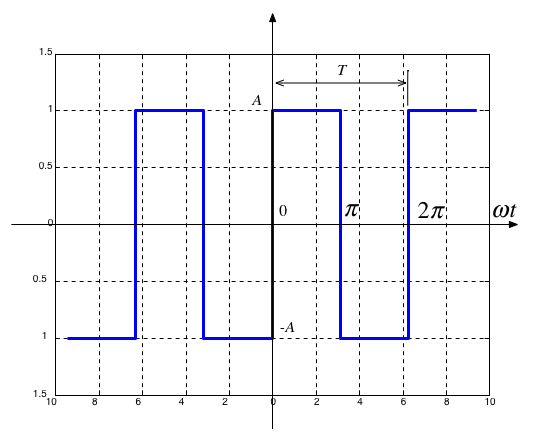

*Fig. 74 *Squarewave with odd-symmetry

a) Compute the Fourier series coefficients $C_k$ for this signal.

syms A theta k Omega_0
assume(k,'integer')
assume(A,'real')
alpha = int(A*exp(-j*k*theta),theta,0,sym(pi))

$$alpha = \frac{A\,\left({\mathrm{e}}^{-\pi \,k\,\mathrm{i}}-1\right)\,\mathrm{i}}{k}$$

beta = int(-A*exp(-j*k*theta),theta,sym(pi),sym(2*pi))

$$beta = \frac{A\,{\mathrm{e}}^{-2\,\pi \,k\,\mathrm{i}}\,\left({\mathrm{e}}^{\pi \,k\,\mathrm{i}}\,\mathrm{i}-\mathrm{i}\right)}{k}$$

C_k = (1/(2*sym(pi)))*(alpha + beta)

$$C\_k = \frac{\frac{A\,\left({\mathrm{e}}^{-\pi \,k\,\mathrm{i}}-1\right)\,\mathrm{i}}{k}+\frac{A\,{\mathrm{e}}^{-2\,\pi \,k\,\mathrm{i}}\,\left({\mathrm{e}}^{\pi \,k\,\mathrm{i}}\,\mathrm{i}-\mathrm{i}\right)}{k}}{2\,\pi }$$

C_k = simplify(C_k)

$$C\_k = \frac{A\,\left({\left(-1\right)}^{k+\frac{1}{2}}-\mathrm{i}\right)}{k\,\pi }$$

K = [1:11];
C_k = subs(C_k,k,K)

$$C\_k = \left(\begin{array}{ccccccccccc} -\frac{2\,A\,\mathrm{i}}{\pi } & 0 & -\frac{2\,A\,\mathrm{i}}{3\,\pi } & 0 & -\frac{2\,A\,\mathrm{i}}{5\,\pi } & 0 & -\frac{2\,A\,\mathrm{i}}{7\,\pi } & 0 & -\frac{2\,A\,\mathrm{i}}{9\,\pi } & 0 & -\frac{2\,A\,\mathrm{i}}{11\,\pi } \end{array}\right)$$

Note that $C_{-k} = C_{k}^*$

C_minus_k = conj(flip(C_k))

$$C\_minus\_k = \left(\begin{array}{ccccccccccc} \frac{2\,A\,\mathrm{i}}{11\,\pi } & 0 & \frac{2\,A\,\mathrm{i}}{9\,\pi } & 0 & \frac{2\,A\,\mathrm{i}}{7\,\pi } & 0 & \frac{2\,A\,\mathrm{i}}{5\,\pi } & 0 & \frac{2\,A\,\mathrm{i}}{3\,\pi } & 0 & \frac{2\,A\,\mathrm{i}}{\pi } \end{array}\right)$$

C_0 = (1/sym(2*pi))*(int(A,theta,0,sym(pi))+int(-A,theta,sym(pi),sym(2*pi)))

$$C\_0 = 0$$


C_k_array = [C_minus_k,C_0,C_k]

$$C\_k\_array = \left(\begin{array}{ccccccccccccccccccccccc} \frac{2\,A\,\mathrm{i}}{11\,\pi } & 0 & \frac{2\,A\,\mathrm{i}}{9\,\pi } & 0 & \frac{2\,A\,\mathrm{i}}{7\,\pi } & 0 & \frac{2\,A\,\mathrm{i}}{5\,\pi } & 0 & \frac{2\,A\,\mathrm{i}}{3\,\pi } & 0 & \frac{2\,A\,\mathrm{i}}{\pi } & 0 & -\frac{2\,A\,\mathrm{i}}{\pi } & 0 & -\frac{2\,A\,\mathrm{i}}{3\,\pi } & 0 & -\frac{2\,A\,\mathrm{i}}{5\,\pi } & 0 & -\frac{2\,A\,\mathrm{i}}{7\,\pi } & 0 & -\frac{2\,A\,\mathrm{i}}{9\,\pi } & 0 & -\frac{2\,A\,\mathrm{i}}{11\,\pi } \end{array}\right)$$

Calculate and plot spectrum

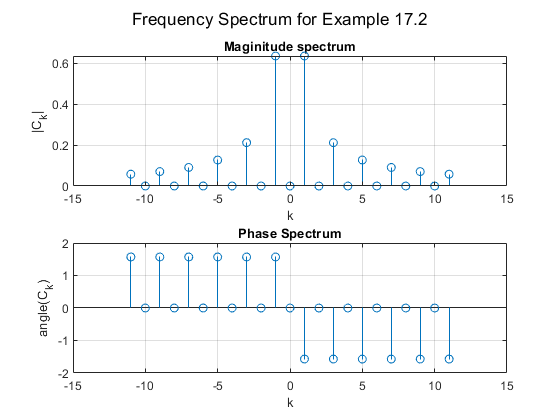

spectrum = subs(C_k_array,A,1);
mag = double(abs(spectrum));
phase = double(angle(spectrum));
subplot(211)
stem(-11:11,mag),...
    grid,title('Maginitude spectrum'),xlabel('k'),ylabel('|C_k|')
subplot(212)
stem(-11:11,phase),...
    grid,title('Phase Spectrum'),xlabel('k'),ylabel('angle(C_k)')
sgtitle('Frequency Spectrum for Example 17.2')

b) Give an expression for the trig. Fourier series for this signal.

b_k = j*(C_k-conj(C_k))

$$b\_k = \left(\begin{array}{ccccccccccc} \frac{4\,A}{\pi } & 0 & \frac{4\,A}{3\,\pi } & 0 & \frac{4\,A}{5\,\pi } & 0 & \frac{4\,A}{7\,\pi } & 0 & \frac{4\,A}{9\,\pi } & 0 & \frac{4\,A}{11\,\pi } \end{array}\right)$$

a_0 = 2*C_0

$$a\_0 = 0$$

ft = a_0/2;
for n = K
    ft = ft + b_k(n)*sin(n*Omega_0*t);
end
ft

$$ft = \frac{4\,A\,\sin\left(\Omega_{0}\,t\right)}{\pi }+\frac{4\,A\,\sin\left(3\,\Omega_{0}\,t\right)}{3\,\pi }+\frac{4\,A\,\sin\left(5\,\Omega_{0}\,t\right)}{5\,\pi }+\frac{4\,A\,\sin\left(7\,\Omega_{0}\,t\right)}{7\,\pi }+\frac{4\,A\,\sin\left(9\,\Omega_{0}\,t\right)}{9\,\pi }+\frac{4\,A\,\sin\left(11\,\Omega_{0}\,t\right)}{11\,\pi }$$

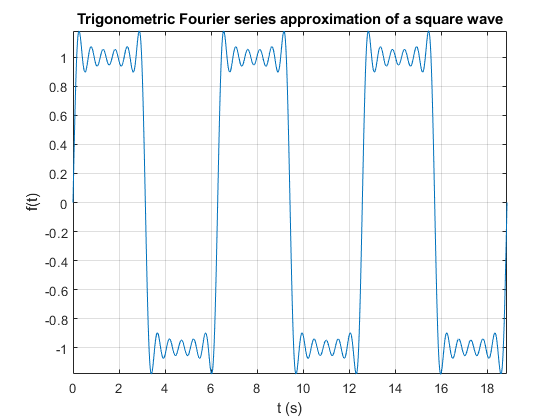

figure
fplot(subs(ft,[A,Omega_0],[1,1]),[0,6*pi]),...
    grid,title('Trigonometric Fourier series approximation of a square wave'),...
    xlabel('t (s)'),ylabel('f(t)')